## Tutorial 6: EXTRACT as a post-processing tool

In this short tutorial, we will show how to utilize EXTRACT as a post-processing tool to estimate cells' calcium activity traces given their spatial profiles. To illustrate how, we will use the movie from the first tutorial.

setupEXTRACT;

load(fullfile(whichEXTRACT(),"Learning materials",...
    "Sample data","example.mat")); 
M = M-1; % ground truth movie with F = 0;
S = S_ground(:,1:15);

We now initialize EXTRACT with the first 15 cells, with the other 5 being 'undetected', simulating the existence of neuropil and other contamination sources. Then, we compute both the robust traces and the least-squares estimates:

config=[];
config = get_defaults(config); 
config.avg_cell_radius=7;
config.S_init = S;
config.preprocess = 0; %using a preprocessed movie
config.F_per_pixel = ones(50,50); % F values are all one
config.trace_output_option='no_constraint';
config.use_gpu=0; 
config.regression_only = 1;
output_rb=extractor(M,config);

15-Jul-2024 21:01:53: Signal extraction will run on 1 partitions serially... 
15-Jul-2024 21:01:53: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Using the provided pre-processed movie...
	 	 	 Initializing using provided images (15 cells)...
	 	 	 Skipping cell refinement module...
	 	 	 Providing traces with robust regression and no non-negativity constraint... 
	 	 	 Count: 15 cells.
15-Jul-2024 21:01:57: Total of 15 cells are found.
15-Jul-2024 21:01:57: Removing duplicate cells...
15-Jul-2024 21:01:57: 15 cells were retained after removing duplicates (cor_thresh = 0.99). 
15-Jul-2024 21:01:57: All done with EXTRACT! 


T_ex = output_rb.temporal_weights';
config.trace_output_option='least_squares';
output_ls=extractor(M,config);

15-Jul-2024 21:01:57: Signal extraction will run on 1 partitions serially... 
15-Jul-2024 21:01:57: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Using the provided pre-processed movie...
	 	 	 Initializing using provided images (15 cells)...
	 	 	 Skipping cell refinement module...
	 	 	 Providing least squares traces... 
	 	 	 Count: 15 cells.
15-Jul-2024 21:01:59: Total of 15 cells are found.
15-Jul-2024 21:01:59: Removing duplicate cells...
15-Jul-2024 21:01:59: 15 cells were retained after removing duplicates (cor_thresh = 0.99). 
15-Jul-2024 21:01:59: All done with EXTRACT! 


T_ls = output_ls.temporal_weights';

Once the flag 'regression_only' is true, EXTRACT skips the cell finding and refinement modules. In this scenario, 'S_init' should contain the spatial profiles (2D or 3D, both acceptable). The extracted calcium activity traces are then as follows:

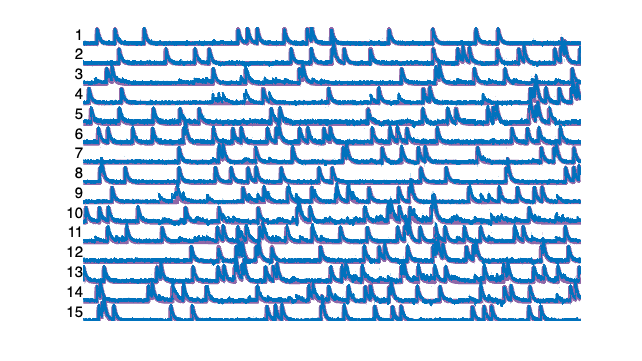

color_extract = [0 0.4470 0.7410];
color_gt      = [144 103 167]./255;
color_l2 = [ 0.8500    0.3250    0.0980];
plot_stacked_traces_double(T_ground(1:15,:), ...
    T_ex,1,{color_gt,color_extract},[],[],{5,3});

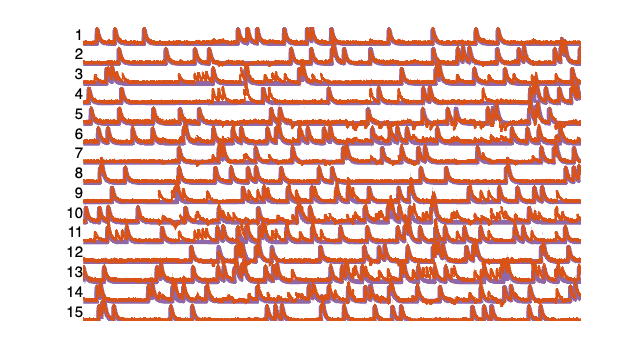

plot_stacked_traces_double(T_ground(1:15,:), ...
    T_ls,1,{color_gt,color_l2},[],[],{5,3});

Note that both calcium traces include occasional contamination, though robust regression preferentially suppresses the contamination compared to the least-squares estimates.